net = load("trafficSignsWeek3Classifier.mat")

net = struct with fields:
    net: [1×1 DAGNetwork]


img = imread("sign011721.png");
% img = imresize(img, net.net.Layers(1).InputSize)

net.net.Layers(1).InputSize

ans =    224   224     3


size(img)

ans =    124   122     3


img = imresize(img, [224, 224]);

[pred, score] = classify(net.net, img);

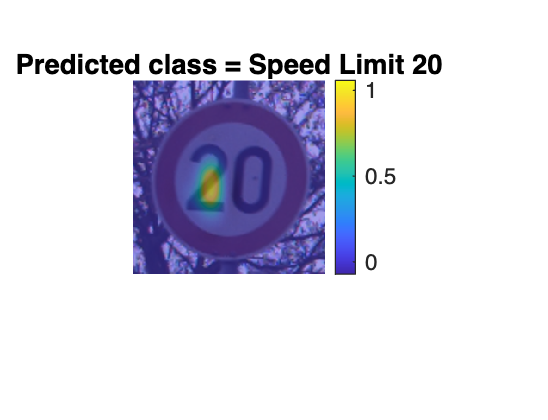

map = occlusionSensitivity(net.net, img, pred);
imshow(img)
hold on
imagesc(map, "AlphaData",0.5)
hold off
colorbar
title("Predicted class = " + string(replace(string(pred), "_", " ")))
set(gca,'TickLabelInterpreter','none');

img = imread("sign12396.png");

img = imresize(img, [224, 224]);

[pred, score] = classify(net.net, img);

pred

pred = categorical
     Speed Limit 80 


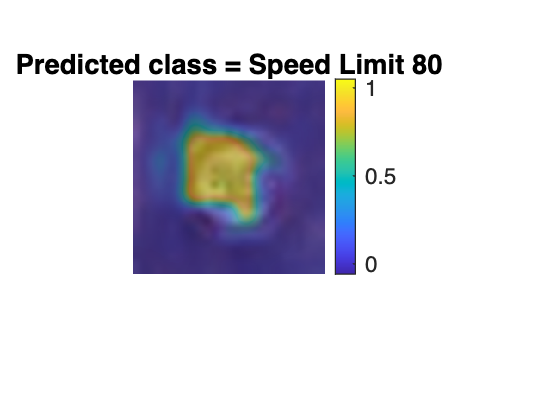

map = occlusionSensitivity(net.net, img, pred);
imshow(img)
hold on
imagesc(map, "AlphaData",0.5)
hold off
colorbar
title("Predicted class = " + string(replace(string(pred), "_", " ")))
set(gca,'TickLabelInterpreter','none');

max(score)

ans = single
0.9481